clear;

profile = Profile.ski;
clockTimeLimit = 30; % 体験時間 (s)
period = 5; % 歩行周期 (s)

legForwardTimeRate = 3; % 足スライダ前進 時間比
legBackwardTimeRate = 2; % 足スライダ後退 時間比

stockForwardTimeRate = 3; % ストックスライダ前進 時間比
stockBackwardTimeRate = 2; % ストックスライダ後退 時間比

upTimeRate = 5; % 伸縮 持ち上げ 時間比
downTimeRate = 1; % 伸縮 降下 時間比

stockFlyingTimeRate = 3.2; % ストック空中時間比
stockGroundTimeRate = 1.8; % ストック接地時間比

tiltBackwardTimeRate = stockForwardTimeRate;
tiltForwardTimeRate = stockBackwardTimeRate;

liftLength = 20; % 椅子 リフト長 単位 (mm)
pedalLength = 60; % ペダル長 単位 (mm)
seatSlideLength = 200; % 椅子 スライド長 単位 (mm)
extendLength = 80; % 伸縮長 単位 (mm)
stockSlideLength = 300; % ストック スライド長 単位 (mm)
tiltBackwardDeg = 10; % ストック 後傾角度 (deg)
tiltForwardDeg = -10; % ストック 前傾角度 (deg)


椅子 リフト

L = liftLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
if legForwardTimeRate < legBackwardTimeRate
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
else
    clockTimeU = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
    clockTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) + period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate)/2; % 単位 (s)
    deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
    deltaTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate) * 1/2; % 単位 (s)
end
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period/2:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period/2:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

lifter = table(clockTime, deltaTime, absolutePosition, useStiffness)

lifter = 23×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         3           1               20                0      
         4           1                0                0      
       5.5           1               20                0      
       6.5           1                0                0      
         8           1               20                0      
         9           1                0                0      
      10.5           1               20                0      
      11.5           1                0                0      
        13           1               20                0      
        14           1                0                0      
      15.5           1               20                0      
      16.5           1                0                0      
        18           1               20                0      
        19           1            

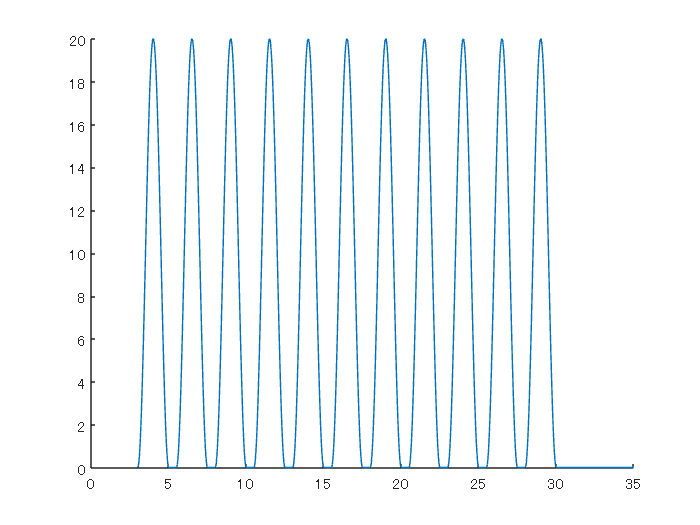

writetable(lifter, "lifter.csv");
figure;
[lifter_x, lifter_t] = showGraph(clockTime, deltaTime, absolutePosition);


% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)


左ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftPedal = 13×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         3            2              60                0      
         5            3               0                0      
         8            2              60                0      
        10            3               0                0      
        13            2              60                0      
        15            3               0                0      
        18            2              60                0      
        20            3               0                0      
        23            2              60                0      
        25            3               0                0      
        28            2              60                0      
        30            3               0                0      
      32.5          2.5               0                0      


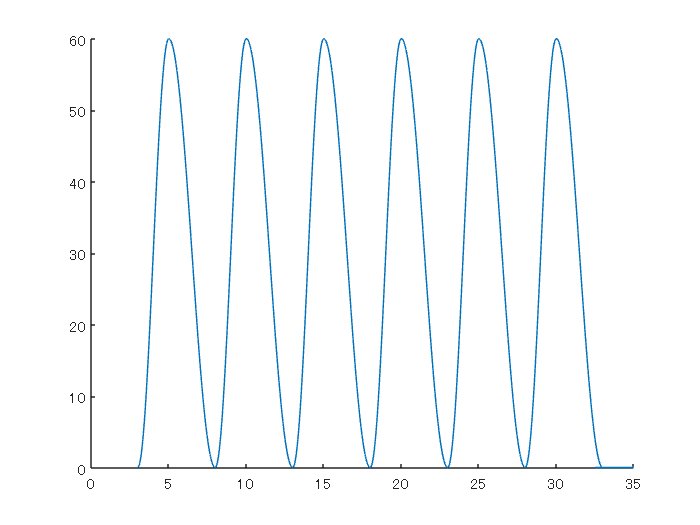

writetable(leftPedal, "leftPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[leftPedal_x, leftPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ペダル

L = pedalLength; % スライド長 単位 (mm)
startClockTime = period/2 + period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 開始時刻 (s)
clockTimeU = 0; % 単位 (s)
clockTimeD = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeU = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeD = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionU = L; % 単位 (mm)
positionD = 0; % 単位 (mm)

clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
tmp = [clockTimeUList; clockTimeDList];
clockTime = tmp(:);
deltaTimeUList = deltaTimeU + 0*clockTimeUList;
deltaTimeDList = deltaTimeD + 0*clockTimeDList;
tmp = [deltaTimeUList; deltaTimeDList];
deltaTime = tmp(:);
positionUList = positionU + 0*clockTimeUList;
positionDList = positionD + 0*clockTimeDList;
tmp = [positionUList; positionDList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightPedal = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightPedal = 11×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       5.5            2              60                0      
       7.5            3               0                0      
      10.5            2              60                0      
      12.5            3               0                0      
      15.5            2              60                0      
      17.5            3               0                0      
      20.5            2              60                0      
      22.5            3               0                0      
      25.5            2              60                0      
      27.5            3               0                0      
      32.5          2.5               0                0      


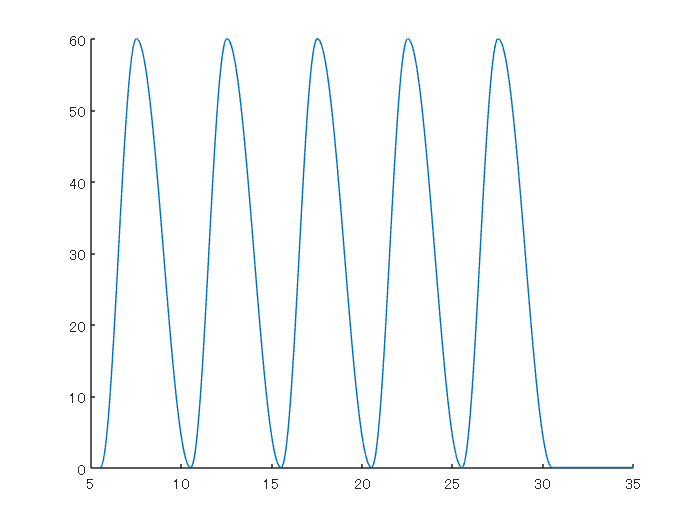

writetable(rightPedal, "rightPedal.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[rightPedal_x, rightPedal_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　左　スライダ

L = seatSlideLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatLeftSlider = 13×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0            3              100               0      
         3            2             -100               0      
         5            3              100               0      
         8            2             -100               0      
        10            3              100               0      
        13            2             -100               0      
        15            3              100               0      
        18            2             -100               0      
        20            3              100               0      
        23            2             -100               0      
        25            3              100               0      
        28            2             -100               0      
      32.5          2.5                0               0      


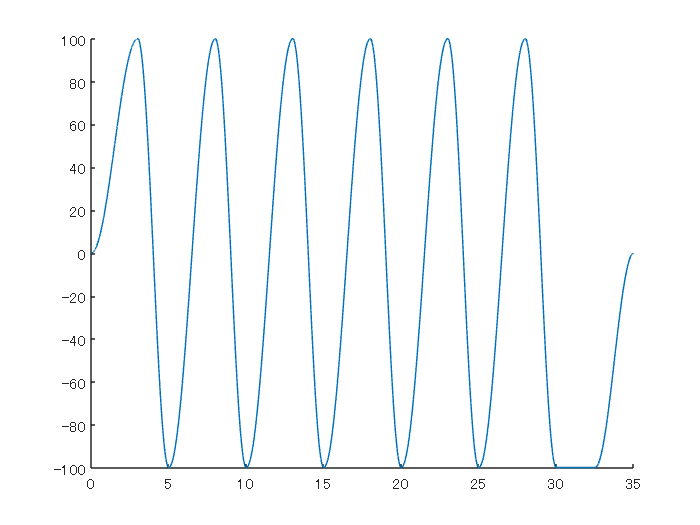

writetable(seatLeftSlider, "seatLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatLeftSlider_x, seatLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

椅子　右　スライダ

L = seatSlideLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeF = period*legForwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
deltaTimeB = period*legBackwardTimeRate/(legForwardTimeRate + legBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

seatRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

seatRightSlider = 11×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       2.5            3              100               0      
       5.5            2             -100               0      
       7.5            3              100               0      
      10.5            2             -100               0      
      12.5            3              100               0      
      15.5            2             -100               0      
      17.5            3              100               0      
      20.5            2             -100               0      
      22.5            3              100               0      
      25.5            2             -100               0      
      32.5          2.5                0               0      


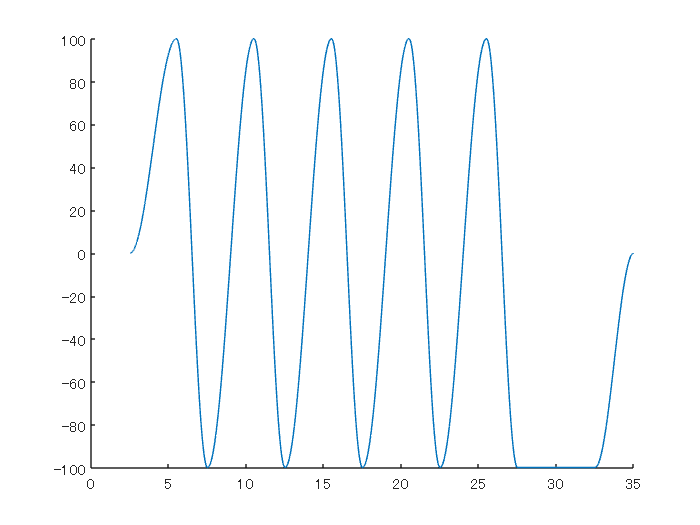

writetable(seatRightSlider, "seatRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
figure;
[seatRightSlider_x, seatRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

if profile == Profile.walk

左ストックの伸縮　登山

    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　登山


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeU = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList)]));
    tmp = [clockTimeUList; clockTimeDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    tmp = [deltaTimeUList; deltaTimeDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    tmp = [positionUList; positionDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList))];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

if profile == Profile.ski

左ストックの伸縮 クロスカントリー


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = period/2; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);

    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockLeftExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockLeftExtend, "stockLeftExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    figure;
    [stockLeftExtend_x, stockLeftExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックの伸縮　クロスカントリー

stockLeftExtend = 16×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

        2.5        2.6667              80              0      
     5.1667       0.53333          53.333              1      
        5.8           1.7               0              0      
        7.5        2.6667              80              0      
     10.167       0.53333          53.333              1      
       10.8           1.7               0              0      
       12.5        2.6667              80              0      
     15.167       0.53333          53.333              1      
       15.8           1.7               0              0      
       17.5        2.6667              80              0      
     20.167       0.53333          53.333              1      
       20.8           1.7               0              0      
       22.5        2.6667              80              0      
     25.167       0.53333

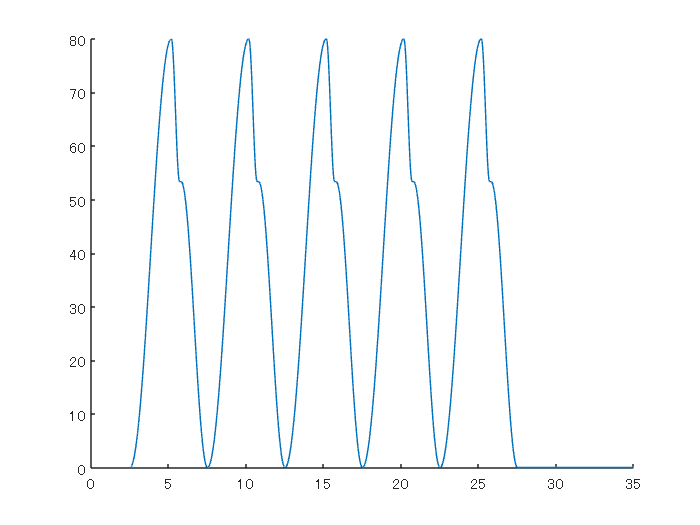

stockRightExtend = 19×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

          0        2.6667              80              0      
     2.6667       0.53333          53.333              1      
        3.3           1.7               0              0      
          5        2.6667              80              0      
     7.6667       0.53333          53.333              1      
        8.3           1.7               0              0      
         10        2.6667              80              0      
     12.667       0.53333          53.333              1      
       13.3           1.7               0              0      
         15        2.6667              80              0      
     17.667       0.53333          53.333              1      
       18.3           1.7               0              0      
         20        2.6667              80              0      
     22.667       0.5333

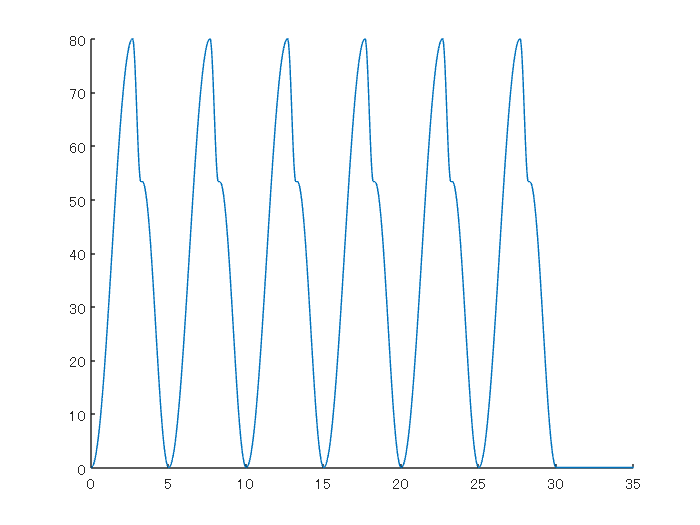


    L = extendLength; % スライド長 単位 (mm)
    startClockTime = 0; % 開始時刻 (s)
    clockTimeU = 0; % 単位 (s)
    clockTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    clockTimeSlowD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) + 0.1; % 単位 (s)
    deltaTimeU = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * upTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeD = period*stockFlyingTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) * downTimeRate/(upTimeRate + downTimeRate); % 単位 (s)
    deltaTimeSlowD = period*stockGroundTimeRate/(stockFlyingTimeRate + stockGroundTimeRate) - 0.1; % 単位 (s)
    positionU = L; % 単位 (mm)
    positionD = 2*L/3; % 単位 (mm)
    positionSlowD = 0; % 単位 (mm)

    clockTimeUList = (startClockTime + clockTimeU):period:clockTimeLimit; % 単位 (s)
    clockTimeDList = (startClockTime + clockTimeD):period:clockTimeLimit; % 単位 (s)
    clockTimeSlowDList = (startClockTime + clockTimeSlowD):period:clockTimeLimit; % 単位 (s)
    clockTimeUList = clockTimeUList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeDList = clockTimeDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    clockTimeSlowDList = clockTimeSlowDList(1:min([length(clockTimeUList), length(clockTimeDList), length(clockTimeSlowDList)]));
    tmp = [clockTimeUList; clockTimeDList; clockTimeSlowDList];
    clockTime = tmp(:);
    deltaTimeUList = deltaTimeU + 0*clockTimeUList;
    deltaTimeDList = deltaTimeD + 0*clockTimeDList;
    deltaTimeSlowDList = deltaTimeSlowD + 0*clockTimeSlowDList;
    tmp = [deltaTimeUList; deltaTimeDList; deltaTimeSlowDList];
    deltaTime = tmp(:);
    positionUList = positionU + 0*clockTimeUList;
    positionDList = positionD + 0*clockTimeDList;
    positionSlowDList = positionSlowD + 0*clockTimeSlowDList;
    tmp = [positionUList; positionDList; positionSlowDList];
    absolutePosition = tmp(:);
    tmp = [zeros(size(clockTimeUList)); ones(size(clockTimeDList)); zeros(size(clockTimeSlowDList));];
    useStiffness = tmp(:);

    clockTime(end+1) = clockTimeLimit + period/2;
    deltaTime(end+1) = period/2;
    absolutePosition(end+1) = 0;
    useStiffness(end+1) = 0;

    stockRightExtend = table(clockTime, deltaTime, absolutePosition, useStiffness)
    writetable(stockRightExtend, "stockRightExtend.csv");
    % figure;
    % showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
    figure;
    [stockRightExtend_x, stockRightExtend_t] = showGraph(clockTime, deltaTime, absolutePosition);
end

左ストックのスライダ


L = stockSlideLength; % スライド長 単位 (mm)
startClockTime = period/2; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockLeftSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockLeftSlider = 11×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       2.5            3              150               0      
       5.5            2             -150               0      
       7.5            3              150               0      
      10.5            2             -150               0      
      12.5            3              150               0      
      15.5            2             -150               0      
      17.5            3              150               0      
      20.5            2             -150               0      
      22.5            3              150               0      
      25.5            2             -150               0      
      32.5          2.5                0               0      


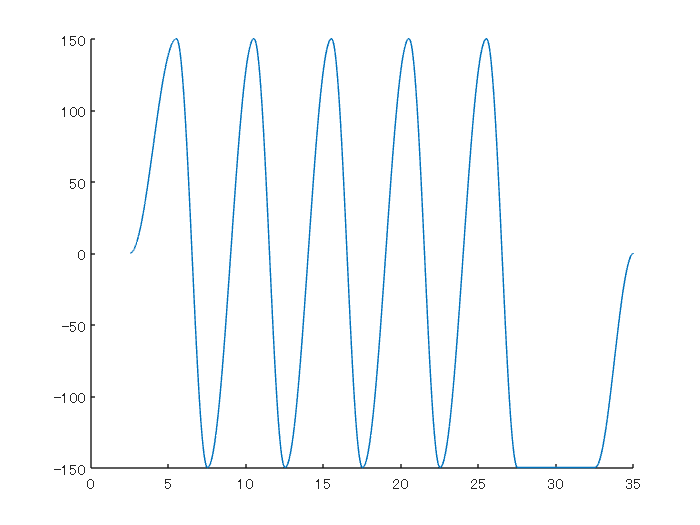

writetable(stockLeftSlider, "stockLeftSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockLeftSlider_x, stockLeftSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストックのスライダ


L = stockSlideLength; % スライド長 単位 (mm)
startClockTime = 0; % 開始時刻 (s)
clockTimeF = 0; % 単位 (s)
clockTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionF = L/2; % 単位 (mm)
positionB = -L/2; % 単位 (mm)

clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeFList; clockTimeBList];
clockTime = tmp(:);
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
tmp = [deltaTimeFList; deltaTimeBList];
deltaTime = tmp(:);
positionFList = positionF + 0*clockTimeFList;
positionBList = positionB + 0*clockTimeBList;
tmp = [positionFList; positionBList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

stockRightSlider = table(clockTime, deltaTime, absolutePosition, useStiffness)

stockRightSlider = 13×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0            3              150               0      
         3            2             -150               0      
         5            3              150               0      
         8            2             -150               0      
        10            3              150               0      
        13            2             -150               0      
        15            3              150               0      
        18            2             -150               0      
        20            3              150               0      
        23            2             -150               0      
        25            3              150               0      
        28            2             -150               0      
      32.5          2.5                0               0      


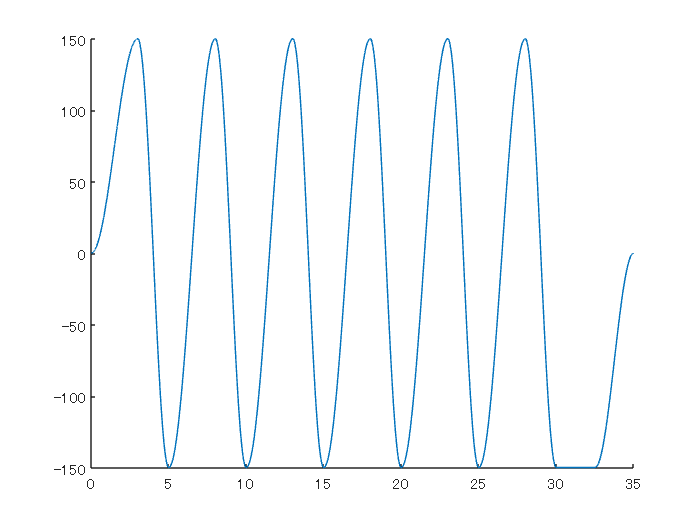

writetable(stockRightSlider, "stockRightSlider.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[stockRightSlider_x, stockRightSlider_t] = showGraph(clockTime, deltaTime, absolutePosition);

左ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTime = period/2; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

leftTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

leftTilt = 11×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

       2.5            3              10                0      
       5.5            2             -10                0      
       7.5            3              10                0      
      10.5            2             -10                0      
      12.5            3              10                0      
      15.5            2             -10                0      
      17.5            3              10                0      
      20.5            2             -10                0      
      22.5            3              10                0      
      25.5            2             -10                0      
      32.5          2.5               0                0      


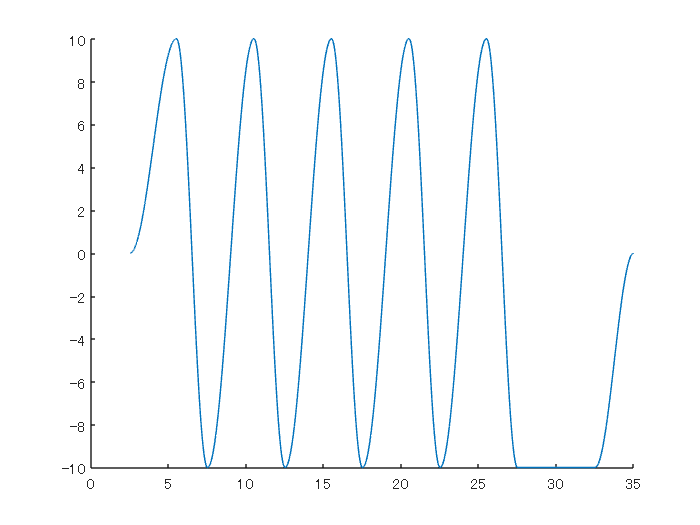

writetable(leftTilt, "leftTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[leftTilt_x, leftTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);

右ストック 前後傾

LF = tiltForwardDeg; % 単位 (deg)
LB = tiltBackwardDeg; % 単位 (deg)
startClockTime = 0; % 開始時刻 (s)
clockTimeB = 0; % 単位 (s)
clockTimeF = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeB = period*stockForwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
deltaTimeF = period*stockBackwardTimeRate/(stockForwardTimeRate + stockBackwardTimeRate); % 単位 (s)
positionB = LB; % 単位 (deg)
positionF = LF; % 単位 (deg)

clockTimeBList = (startClockTime + clockTimeB):period:clockTimeLimit; % 単位 (s)
clockTimeFList = (startClockTime + clockTimeF):period:clockTimeLimit; % 単位 (s)
clockTimeBList = clockTimeBList(1:min([length(clockTimeFList), length(clockTimeBList)]));
clockTimeFList = clockTimeFList(1:min([length(clockTimeFList), length(clockTimeBList)]));
tmp = [clockTimeBList; clockTimeFList];
clockTime = tmp(:);
deltaTimeBList = deltaTimeB + 0*clockTimeBList;
deltaTimeFList = deltaTimeF + 0*clockTimeFList;
tmp = [deltaTimeBList; deltaTimeFList];
deltaTime = tmp(:);
positionBList = positionB + 0*clockTimeBList;
positionFList = positionF + 0*clockTimeFList;
tmp = [positionBList; positionFList];
absolutePosition = tmp(:);

clockTime(end+1) = clockTimeLimit + period/2;
deltaTime(end+1) = period/2;
absolutePosition(end+1) = 0;

useStiffness = zeros(size(clockTime));

rightTilt = table(clockTime, deltaTime, absolutePosition, useStiffness)

rightTilt = 13×4 table
    clockTime    deltaTime    absolutePosition    useStiffness
    _________    _________    ________________    ____________

         0            3              10                0      
         3            2             -10                0      
         5            3              10                0      
         8            2             -10                0      
        10            3              10                0      
        13            2             -10                0      
        15            3              10                0      
        18            2             -10                0      
        20            3              10                0      
        23            2             -10                0      
        25            3              10                0      
        28            2             -10                0      
      32.5          2.5               0                0      


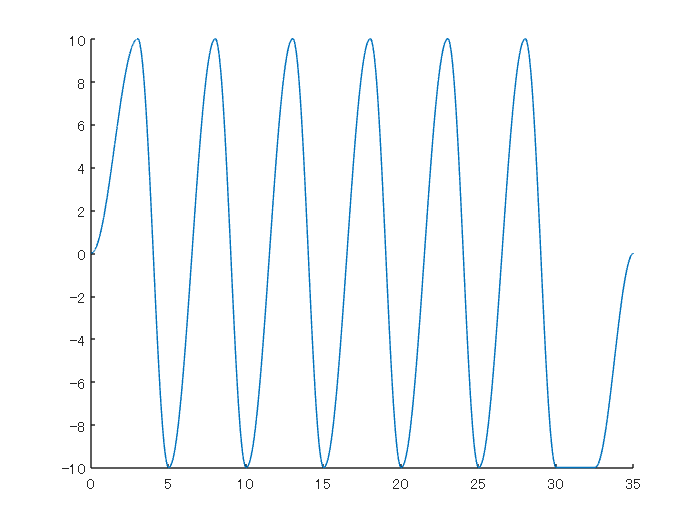

writetable(rightTilt, "rightTilt.csv");
% figure;
% showGraphEveryCmd(clockTime, deltaTime, absolutePosition);
figure;
[rightTilt_x, rightTilt_t] = showGraph(clockTime, deltaTime, absolutePosition);


signal_lifter = timeseries(lifter_x, lifter_t, Name='lifter');
signal_leftPedal = timeseries(leftPedal_x, leftPedal_t, Name='leftPedal');
signal_rightPedal = timeseries(rightPedal_x, rightPedal_t, Name='rightPedal');
signal_seatLeftSlider = timeseries(seatLeftSlider_x, seatLeftSlider_t, Name='seatLeftSlider');
signal_seatRightSlider = timeseries(seatRightSlider_x, seatRightSlider_t, Name='seatRightSlider');
signal_stockLeftSlider = timeseries(stockLeftSlider_x, stockLeftSlider_t, Name='stockLeftSlider');
signal_stockRightSlider = timeseries(stockRightSlider_x, stockRightSlider_t, Name='stockRightSlider');
signal_stockLeftExtend = timeseries(stockLeftExtend_x, stockLeftExtend_t, Name='stockLeftExtend');
signal_stockRightExtend = timeseries(stockRightExtend_x, stockRightExtend_t, Name='stockRightExtend');
signal_leftTilt = timeseries(leftTilt_x, leftTilt_t, Name="leftTilt");
signal_rightTilt = timeseries(rightTilt_x, rightTilt_t, Name="rightTilt");

Scenario = Simulink.SimulationData.Dataset;

Scenario{1} = signal_lifter;
Scenario{2} = signal_leftPedal;
Scenario{3} = signal_rightPedal;
Scenario{4} = signal_seatLeftSlider;
Scenario{5} = signal_seatRightSlider;
Scenario{6} = signal_stockLeftExtend;
Scenario{7} = signal_stockRightExtend;
Scenario{8} = signal_stockLeftSlider;
Scenario{9} = signal_stockRightSlider;
Scenario{10} = signal_leftTilt;
Scenario{11} = signal_rightTilt;


% Scenario{2} = SignalStickRightPitch;
% Scenario{2}.Name = 'SignalStickRightPitch';
% Scenario{5} = signal_stockLeftPitch;
% Scenario{5}.Name = 'SignalStickLeftPitch';

save('scenario.mat', 'Scenario');

clear;

function showGraphEveryCmd(clockTime, deltaTime, absolutePosition)
    t = 0:0.001:deltaTime(1);
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    plot(t + clockTime(1), x);
    hold on;
    for idx = 2:length(clockTime)
        t = 0:0.01:deltaTime(idx);
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        plot(t + clockTime(idx), x);
    end
end

function [ret_x, ret_t] = showGraph(clockTime, deltaTime, absolutePosition)
    % ret_t = [];
    t = (0:0.001:deltaTime(1))';
    x = absolutePosition(1)*(1 + cos(pi*t/deltaTime(1) + pi))/2;
    % plot(t + clockTime(1), x);
    ret_x = x;
    ret_t = t + clockTime(1);
    hold on;
    for idx = 2:length(clockTime)
        t = (0:0.01:deltaTime(idx))';
        x = (absolutePosition(idx) - absolutePosition(idx-1)) * (1 + cos(pi*t/deltaTime(idx) + pi))/2 + absolutePosition(idx - 1);
        % plot(t + clockTime(idx), x);
        ret_t = [ret_t; t + clockTime(idx)];
        ret_x = [ret_x; x];
    end
    plot(ret_t, ret_x);
end